dataset;
p_l = dataset(:,2);
p_l = p_l - p_l(1,1);
p_r = dataset(:,3);
p_r = p_r - p_r(1,1);
t = dataset(:,1);
delta_pl = diff(p_l);
delta_pr = diff(p_r);
delta_t = diff(t);
v_l = delta_pl./delta_t;
v_r = delta_pr./delta_t;
vt = (v_l + v_r)./2;
d = .25;
w = (v_r - v_l)./d;
integrand = w.*delta_t;


for i = 1:length(integrand)
    theta(i,:) = sum(integrand(1:i,:));
end


x_v= (cos(theta).*vt).*delta_t;
y_v = (sin(theta).*vt).*delta_t;


for i = 1:length(x_v)
    x_p(i,:) = sum(x_v(1:i,:));
end


for i = 1:length(y_v)
    y_p(i,:) = sum(y_v(1:i,:));
end

dt = .1

dt = 0.1000

c = 0.1;
t = 0:dt:3.2/c

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


t = t'

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000



x = .3960*cos(2.65*(t*c+1.4))

x =    -0.3337
   -0.3280
   -0.3220
   -0.3158
   -0.3093
   -0.3026
   -0.2958
   -0.2887
   -0.2814
   -0.2739


y =  -.99*sin(c*t + 1.4) +1

y =     0.0244
    0.0228
    0.0212
    0.0198
    0.0185
    0.0172
    0.0161
    0.0150
    0.0141
    0.0132


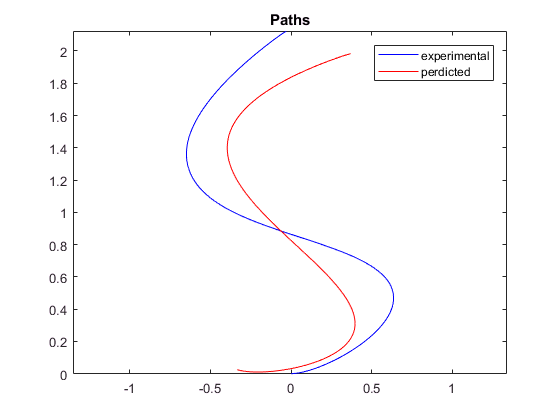


clf
plot(x_p,y_p, 'b')
axis('equal')
hold on 
plot(x,y, 'r')
legend('experimental','perdicted')
title('Paths')